%% DTU 62743 Digital Signal Processing - E25 Exam Solution
% Student Name: Mads Rudolph
% Student ID: s246132
% Exam Date: December 12, 2025

clear; close all; clc;

% Add path to helper functions (adjust as needed)
% addpath('C:\Users\Mads2\DTU\3.semester\DSP\Helpers\');

fprintf('DTU 62743 DSP Exam - December 2025\n');

DTU 62743 DSP Exam - December 2025


fprintf('Date: %s\n\n', datestr(now, 'yyyy-mm-dd HH:MM'));

Date: 2025-12-11 17:11




% Set publication-quality defaults
set(groot, 'defaultFigurePosition', [100 100 900 600]);
set(groot, 'defaultLineLineWidth', 1.5);
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultAxesGridLineStyle', ':');
set(groot, 'defaultAxesGridAlpha', 0.3);

%% ========================================================================
%% PROBLEM 1 (40%) - Z-Domain Analysis
%% ========================================================================

%%
% *Problem 1: Z-Domain Analysis of LTI System*
%
% Given causal discrete-time LTI system T with:
%
% * Zeros: -2, (1+i)/2, (1-i)/2
% * Poles: 0, 1/3, 2/3
% * Constraint: H(1) = 1

%% Problem 1-1: Pole-Zero Diagram

% Define zeros and poles
z1 = -2;
z2 = (1+1i)/2;
z3 = (1-1i)/2;
zeros_H = [z1, z2, z3];

p1 = 0;
p2 = 1/3;
p3 = 2/3;
poles_H = [p1, p2, p3];

fprintf('=== Problem 1-1: Pole-Zero Diagram ===\n\n');

=== Problem 1-1: Pole-Zero Diagram ===




% Display information
fprintf('Zeros:\n');

Zeros:


fprintf('  z1 = %.4f (real)\n', z1);

  z1 = -2.0000 (real)


fprintf('  z2 = %.4f + %.4fi (complex)\n', real(z2), imag(z2));

  z2 = 0.5000 + 0.5000i (complex)


fprintf('  z3 = %.4f - %.4fi (complex conjugate)\n', real(z3), imag(z3));

  z3 = 0.5000 - -0.5000i (complex conjugate)


fprintf('  |z1| = %.4f, |z2| = |z3| = %.4f\n\n', abs(z1), abs(z2));

  |z1| = 2.0000, |z2| = |z3| = 0.7071




fprintf('Poles:\n');

Poles:


fprintf('  p1 = %.4f (at origin)\n', p1);

  p1 = 0.0000 (at origin)


fprintf('  p2 = %.4f (real)\n', p2);

  p2 = 0.3333 (real)


fprintf('  p3 = %.4f (real)\n', p3);

  p3 = 0.6667 (real)


fprintf('  |p1| = %.4f, |p2| = %.4f, |p3| = %.4f\n\n', abs(p1), abs(p2), abs(p3));

  |p1| = 0.0000, |p2| = 0.3333, |p3| = 0.6667



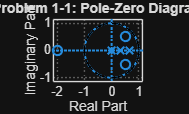


% Construct transfer function polynomials
B1 = poly(zeros_H);
A1 = poly(poles_H);

% Plot pole-zero diagram
figure('Name', 'Problem 1-1: Pole-Zero Diagram');
zplane(B1, A1);
title('Problem 1-1: Pole-Zero Diagram');
grid on;

% Add unit circle
hold on;
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1);
hold off;


%% Problem 1-2: Transfer Function H(z) and ROC

fprintf('\n=== Problem 1-2: Transfer Function ===\n\n');


=== Problem 1-2: Transfer Function ===




% Apply normalization to get H(1) = 1
H1_at_1 = polyval(B1, 1) / polyval(A1, 1);
K = 1 / H1_at_1;
B1_norm = K * B1;

fprintf('Normalization constant K = %.6f\n', K);

Normalization constant K = 0.148148


fprintf('Verification: H(1) = %.6f\n\n', polyval(B1_norm,1)/polyval(A1,1));

Verification: H(1) = 1.000000




% Display transfer function
H1_sys = tf(B1_norm, A1, -1, 'Variable', 'z^-1');
fprintf('Transfer function H(z):\n');

Transfer function H(z):


disp(H1_sys);

  tf with properties:

       Numerator: {[0.1481 0.1481 -0.2222 0.1481]}
     Denominator: {[1 -1 0.2222 0]}
        Variable: 'z^-1'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: -1
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




fprintf('ROC: |z| > %.4f (causal system)\n\n', max(abs(poles_H)));

ROC: |z| > 0.6667 (causal system)




%% Problem 1-3: Stability Analysis

fprintf('=== Problem 1-3: Stability ===\n\n');

=== Problem 1-3: Stability ===




stable = true;
for i = 1:length(poles_H)
    mag = abs(poles_H(i));
    fprintf('Pole %d: |p| = %.4f', i, mag);
    if mag < 1
        fprintf(' < 1 -> STABLE\n');
    else
        fprintf(' >= 1 -> UNSTABLE\n');
        stable = false;
    end
end

Pole 1: |p| = 0.0000

 < 1 -> STABLE


Pole 2: |p| = 0.3333

 < 1 -> STABLE


Pole 3: |p| = 0.6667

 < 1 -> STABLE



fprintf('\n');
if stable
    fprintf('System is STABLE: All poles inside unit circle\n\n');
else
    fprintf('System is UNSTABLE\n\n');
end

System is STABLE: All poles inside unit circle




%% Problem 1-4: Z-Transform of Signal

fprintf('=== Problem 1-4: Z-Transform ===\n\n');

=== Problem 1-4: Z-Transform ===




% Given: x1[n] = (sqrt(2)/2)^n * sin(pi/4 * n) * u[n]
a = sqrt(2)/2;
w0 = pi/4;

fprintf('Signal: x1[n] = (%.4f)^n * sin(%.4f*n) * u[n]\n\n', a, w0);

Signal: x1[n] = (0.7071)^n * sin(0.7854*n) * u[n]




% Apply formula: Z{a^n sin(w0*n) u[n]} = (a*sin(w0)*z^-1) / (1 - 2a*cos(w0)*z^-1 + a^2*z^-2)
sin_w0 = sin(w0);
cos_w0 = cos(w0);

num_X1 = [0, a*sin_w0, 0];
den_X1 = [1, -2*a*cos_w0, a^2];

fprintf('X1(z) numerator:   [%.4f, %.4f, %.4f]\n', num_X1);

X1(z) numerator:   [0.0000, 0.5000, 0.0000]


fprintf('X1(z) denominator: [%.4f, %.4f, %.4f]\n\n', den_X1);

X1(z) denominator: [1.0000, -1.0000, 0.5000]




X1_sys = tf(num_X1, den_X1, -1, 'Variable', 'z^-1');
fprintf('X1(z) =\n');

X1(z) =


disp(X1_sys);

  tf with properties:

       Numerator: {[0 0.5000 0]}
     Denominator: {[1 -1.0000 0.5000]}
        Variable: 'z^-1'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: -1
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




fprintf('ROC: |z| > %.4f\n\n', a);

ROC: |z| > 0.7071




%% Problem 1-5: Output Z-Transform Y1(z)

fprintf('=== Problem 1-5: Output Z-Transform ===\n\n');

=== Problem 1-5: Output Z-Transform ===




% Y1(z) = H(z) * X1(z)
num_Y1 = conv(B1_norm, num_X1);
den_Y1 = conv(A1, den_X1);

fprintf('Y1(z) = H(z) * X1(z)\n\n');

Y1(z) = H(z) * X1(z)



Y1_sys = tf(num_Y1, den_Y1, -1, 'Variable', 'z^-1');
fprintf('Y1(z) =\n');

Y1(z) =


disp(Y1_sys);

  tf with properties:

       Numerator: {[0 0.0741 0.0741 -0.1111 0.0741]}
     Denominator: {[1 -2 1.7222 -0.7222 0.1111]}
        Variable: 'z^-1'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: -1
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




fprintf('This is in irreducible form\n\n');

This is in irreducible form




%% Problem 1-6: Output Signal y1[n]

fprintf('=== Problem 1-6: Output Signal ===\n\n');

=== Problem 1-6: Output Signal ===



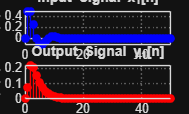


% Generate input signal
n1 = 0:50;
x1_n = (a.^n1) .* sin(w0*n1);

% Filter through system
y1_n = filter(B1_norm, A1, x1_n);

% Plot
figure('Name', 'Problem 1-6: Signals');

subplot(2,1,1);
stem(n1, x1_n, 'b', 'filled');
grid on;
xlabel('n [samples]');
ylabel('x_1[n]');
title('Input Signal x_1[n]');
xlim([0 50]);

subplot(2,1,2);
stem(n1, y1_n, 'r', 'filled');
grid on;
xlabel('n [samples]');
ylabel('y_1[n]');
title('Output Signal y_1[n]');
xlim([0 50]);


fprintf('First 10 values:\n');

First 10 values:


fprintf('n\t x1[n]\t\t y1[n]\n');

n	 x1[n]		 y1[n]


for i = 1:10
    fprintf('%d\t %.4f\t\t %.4f\n', n1(i), x1_n(i), y1_n(i));
end

0	 0.0000		 0.0000
1	 0.5000		 0.0741
2	 0.5000		 0.2222
3	 0.2500		 0.2058
4	 0.0000		 0.1564
5	 -0.1250		 0.1107
6	 -0.1250		 0.0759
7	 -0.0625		 0.0513
8	 -0.0000		 0.0344
9	 0.0313		 0.0230


fprintf('\n');

%% Problem 1-7: Minimum Phase and All-Pass Decomposition

fprintf('=== Problem 1-7: Min-Phase & All-Pass ===\n\n');

=== Problem 1-7: Min-Phase & All-Pass ===




% Identify zeros outside unit circle
zeros_outside = zeros_H(abs(zeros_H) > 1);
fprintf('Zeros outside unit circle: z = %.4f\n\n', zeros_outside);

Zeros outside unit circle: z = -2.0000




% Construct all-pass for z0 = -2
z0_out = zeros_outside(1);
num_ap = -[1, z0_out];      % -(z + z0)
den_ap = [1, 1/z0_out];     % z + 1/z0

fprintf('All-pass system Hap(z):\n');

All-pass system Hap(z):


Hap_sys = tf(num_ap, den_ap, -1, 'Variable', 'z^-1');
disp(Hap_sys);

  tf with properties:

       Numerator: {[-1 2]}
     Denominator: {[1 -0.5000]}
        Variable: 'z^-1'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: -1
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Construct minimum phase (replace outside zero with reflection)
zeros_mp = zeros_H;
zeros_mp(abs(zeros_mp) > 1) = -1/2;
B_mp = poly(zeros_mp);
A_mp = A1;

% Normalize
K_mp = 1 / (polyval(num_ap,1)/polyval(den_ap,1)) / (polyval(B_mp,1)/polyval(A_mp,1));
B_mp = K_mp * B_mp;

fprintf('Minimum phase system Hmp(z):\n');

Minimum phase system Hmp(z):


Hmp_sys = tf(B_mp, A_mp, -1, 'Variable', 'z^-1');
disp(Hmp_sys);

  tf with properties:

       Numerator: {[0.1481 -0.0741 0 0.0370]}
     Denominator: {[1 -1 0.2222 0]}
        Variable: 'z^-1'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: -1
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



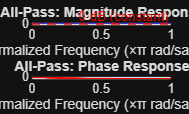


% Plot all-pass frequency response
[H_ap, w_ap] = freqz(num_ap, den_ap, 1024);

figure('Name', 'Problem 1-7: All-Pass Response');

subplot(2,1,1);
plot(w_ap/pi, 20*log10(abs(H_ap)), 'b', 'LineWidth', 1.5);
grid on;
xlabel('Normalized Frequency (×π rad/sample)');
ylabel('Magnitude [dB]');
title('All-Pass: Magnitude Response');
yline(0, '--r', '0 dB (constant)', 'LineWidth', 1.5);
ylim([-5 5]);

subplot(2,1,2);
plot(w_ap/pi, unwrap(angle(H_ap)), 'r', 'LineWidth', 1.5);
grid on;
xlabel('Normalized Frequency (×π rad/sample)');
ylabel('Phase [rad]');
title('All-Pass: Phase Response');


fprintf('Magnitude response shows constant |Hap| = 1 (0 dB) as expected\n\n');

Magnitude response shows constant |Hap| = 1 (0 dB) as expected




%% ========================================================================
%% PROBLEM 2 (30%) - IIR Filter Analysis
%% ========================================================================

%%
% *Problem 2: IIR Lowpass Filter (Direct Form II)*
%
% * Sampling frequency: Fs = 1600 Hz
% * Stated cutoff: 400 Hz at -3 dB

%% Problem 2-1: Transfer Function and Frequency Response

fprintf('========================================\n');

fprintf('PROBLEM 2: IIR FILTER ANALYSIS\n');

PROBLEM 2: IIR FILTER ANALYSIS


fprintf('========================================\n\n');


% Filter coefficients from Direct Form II diagram
B2 = [0.0940, 0.3759, 0.5639, 0.3759, 0.0940];
A2 = [1, 0.4860, 0.0177];
Fs2 = 1600;
Ts2 = 1/Fs2;

fprintf('=== Problem 2-1: Transfer Function ===\n\n');

=== Problem 2-1: Transfer Function ===




% Display transfer function
H2_sys = tf(B2, A2, Ts2, 'Variable', 'z^-1');
fprintf('H(z) =\n');

H(z) =


disp(H2_sys);

  tf with properties:

       Numerator: {[0.0940 0.3759 0.5639 0.3759 0.0940]}
     Denominator: {[1 0.4860 0.0177 0 0]}
        Variable: 'z^-1'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 6.2500e-04
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



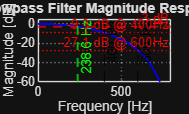


% Compute frequency response
F_vec2 = linspace(0, Fs2/2, 10000);
[H2, F2] = freqz(B2, A2, F_vec2, Fs2);
Mag2_dB = 20*log10(abs(H2));

% Plot magnitude
figure('Name', 'Problem 2-1: Magnitude Response');
plot(F2, Mag2_dB, 'b-', 'LineWidth', 1.5);
hold on;
grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Lowpass Filter Magnitude Response');
xlim([0 Fs2/2]);
ylim([-60 5]);

% Mark -3 dB line and frequencies
yline(-3, '--r', '-3 dB', 'LineWidth', 1.5);
xline(400, '--k', '400 Hz', 'LineWidth', 1);
xline(600, '--k', '600 Hz', 'LineWidth', 1);

% Find actual -3 dB frequency
idx_3dB = find(Mag2_dB >= -3, 1, 'last');
F_3dB = F2(idx_3dB);
xline(F_3dB, '--g', sprintf('%.1f Hz', F_3dB), 'LineWidth', 1.5);

% Find attenuation at 400 and 600 Hz
[~, idx_400] = min(abs(F2 - 400));
[~, idx_600] = min(abs(F2 - 600));
Mag_400 = Mag2_dB(idx_400);
Mag_600 = Mag2_dB(idx_600);

yline(Mag_400, ':', sprintf('%.1f dB @ 400Hz', Mag_400), 'Color', 'r');
yline(Mag_600, ':', sprintf('%.1f dB @ 600Hz', Mag_600), 'Color', 'r');
hold off;


fprintf('Attenuation at key frequencies:\n');

Attenuation at key frequencies:


fprintf('  Measured -3 dB point: %.1f Hz\n', F_3dB);

  Measured -3 dB point: 238.6 Hz


fprintf('  Attenuation at 400 Hz: %.2f dB\n', Mag_400);

  Attenuation at 400 Hz: -9.29 dB


fprintf('  Attenuation at 600 Hz: %.2f dB\n\n', Mag_600);

  Attenuation at 600 Hz: -27.11 dB




if abs(Mag_400 - (-3)) < 1
    fprintf('Filter matches description (−3 dB at 400 Hz)\n');
else
    fprintf('Filter DOES NOT match description\n');
    fprintf('  Expected: -3 dB at 400 Hz\n');
    fprintf('  Actual: %.2f dB at 400 Hz\n', Mag_400);
    fprintf('  Actual -3 dB point: %.1f Hz\n', F_3dB);
end

Filter DOES NOT match description


  Expected: -3 dB at 400 Hz


  Actual: -9.29 dB at 400 Hz


  Actual -3 dB point: 238.6 Hz


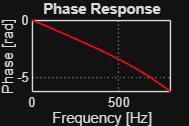

fprintf('\n');

% Phase response
figure('Name', 'Problem 2-1: Phase Response');
plot(F2, unwrap(angle(H2)), 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Frequency [Hz]');
ylabel('Phase [rad]');
title('Phase Response');
xlim([0 Fs2/2]);


fprintf('Phase analysis:\n');

Phase analysis:


fprintf('  Filter type: IIR (Direct Form II with feedback)\n');

  Filter type: IIR (Direct Form II with feedback)


fprintf('  Phase characteristic: NON-LINEAR\n');

  Phase characteristic: NON-LINEAR


fprintf('  Expected? YES - IIR filters do not have linear phase\n');

  Expected? YES - IIR filters do not have linear phase


fprintf('  Only FIR with symmetric coefficients have linear phase\n\n');

  Only FIR with symmetric coefficients have linear phase




%% Problem 2-2: Pole-Zero Diagram and Impulse Response

fprintf('=== Problem 2-2: Pole-Zero & Impulse Response ===\n\n');

=== Problem 2-2: Pole-Zero & Impulse Response ===



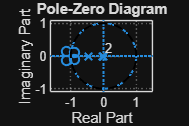


% Pole-zero plot
figure('Name', 'Problem 2-2: Pole-Zero');
zplane(B2, A2);
title('Pole-Zero Diagram');
grid on;
hold on;
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--', 'LineWidth', 1.5);
hold off;


% Analyze stability
poles_2 = roots(A2);
zeros_2 = roots(B2);

fprintf('Poles:\n');

Poles:


stable2 = true;
for i = 1:length(poles_2)
    mag = abs(poles_2(i));
    fprintf('  p%d: |p| = %.4f', i, mag);
    if mag < 1
        fprintf(' < 1 -> STABLE\n');
    else
        fprintf(' >= 1 -> UNSTABLE\n');
        stable2 = false;
    end
end

  p1: |p| = 0.4463

 < 1 -> STABLE


  p2: |p| = 0.0397

 < 1 -> STABLE



fprintf('\n');
if stable2
    fprintf('Filter is STABLE (all poles inside unit circle)\n\n');
else
    fprintf('Filter is UNSTABLE\n\n');
end

Filter is STABLE (all poles inside unit circle)



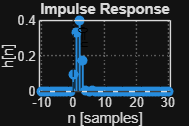


% Impulse response
n2 = -10:30;
impulse_signal = zeros(size(n2));
impulse_signal(n2 == 0) = 1;
h2 = filter(B2, A2, impulse_signal);

figure('Name', 'Problem 2-2: Impulse Response');
stem(n2, h2, 'filled', 'LineWidth', 1.5);
grid on;
xlabel('n [samples]');
ylabel('h[n]');
title('Impulse Response');
xline(0, '--k', 'n=0', 'LineWidth', 1);
yline(0, '--k', 'LineWidth', 0.5);


fprintf('First 10 impulse response values:\n');

First 10 impulse response values:


fprintf('n\t h[n]\n');

n	 h[n]


for i = 1:min(15, length(n2))
    if abs(h2(i)) > 1e-10
        fprintf('%d\t %.6f\n', n2(i), h2(i));
    end
end

0	 0.094000
1	 0.330216
2	 0.401751
3	 0.174804
4	 0.001934


fprintf('\n');

%% Problem 2-3: Signal Sampling

fprintf('=== Problem 2-3: Signal Sampling ===\n\n');

=== Problem 2-3: Signal Sampling ===




% Signal parameters
F1 = 100; A1 = 1;
F2 = 300; A2 = 2;
F3 = 600; A3 = 3;

% Nyquist analysis
F_Nyquist = Fs2/2;
fprintf('Sampling frequency: Fs = %.0f Hz\n', Fs2);

Sampling frequency: Fs = 1600 Hz


fprintf('Nyquist frequency: F_Nyq = %.0f Hz\n\n', F_Nyquist);

Nyquist frequency: F_Nyq = 800 Hz




components = [F1, F2, F3];
for i = 1:3
    fprintf('Component %d: F = %.0f Hz\n', i, components(i));
    if components(i) < F_Nyquist
        fprintf('  %.0f < %.0f -> NO aliasing\n\n', components(i), F_Nyquist);
    else
        fprintf('  %.0f >= %.0f -> ALIASING!\n\n', components(i), F_Nyquist);
    end
end

Component 1: F = 100 Hz


  100 < 800 -> NO aliasing



Component 2: F = 300 Hz


  300 < 800 -> NO aliasing



Component 3: F = 600 Hz


  600 < 800 -> NO aliasing




fprintf('Maximum signal frequency without aliasing: %.0f Hz\n\n', F_Nyquist);

Maximum signal frequency without aliasing: 800 Hz




% Sample signal
t = 0:1/Fs2:0.05;
x_sampled = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t) + A3*cos(2*pi*F3*t);

fprintf('Time vector: t = 0 to %.3f seconds\n', max(t));

Time vector: t = 0 to 0.050 seconds


fprintf('Number of samples: %d\n\n', length(t));

Number of samples: 81



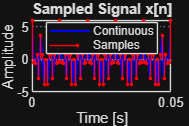


% Plot
figure('Name', 'Problem 2-3: Sampled Signal');
plot(t, x_sampled, 'b-', 'LineWidth', 1.5);
hold on;
stem(t, x_sampled, 'r.', 'MarkerSize', 8);
hold off;
grid on;
xlabel('Time [s]');
ylabel('Amplitude');
title('Sampled Signal x[n]');
xlim([0 0.05]);
legend('Continuous', 'Samples', 'Location', 'best');


%% Problem 2-4: Frequency Spectrum

fprintf('=== Problem 2-4: Frequency Spectrum ===\n\n');

=== Problem 2-4: Frequency Spectrum ===



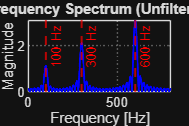


% Compute FFT
N_fft = 2^14;
X_fft = fft(x_sampled, N_fft);
f_fft = (0:N_fft-1) * (Fs2/N_fft);

% One-sided spectrum
X_mag = abs(X_fft) / length(x_sampled);
X_onesided = X_mag(1:N_fft/2+1);
X_onesided(2:end-1) = 2*X_onesided(2:end-1);
f_onesided = f_fft(1:N_fft/2+1);

% Plot
figure('Name', 'Problem 2-4: Frequency Spectrum');
plot(f_onesided, X_onesided, 'b-', 'LineWidth', 1.5);
hold on;
xline(F1, '--r', sprintf('%d Hz', F1), 'LineWidth', 1.5);
xline(F2, '--r', sprintf('%d Hz', F2), 'LineWidth', 1.5);
xline(F3, '--r', sprintf('%d Hz', F3), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude');
title('Frequency Spectrum (Unfiltered)');
xlim([0 Fs2/2]);


% Find peaks
[pks, locs] = findpeaks(X_onesided, 'MinPeakHeight', 0.1);
freq_peaks = f_onesided(locs);

fprintf('Detected frequency components:\n');

Detected frequency components:


fprintf('Freq [Hz]\t Magnitude\n');

Freq [Hz]	 Magnitude


for i = 1:length(freq_peaks)
    fprintf('%.1f\t\t %.3f\n', freq_peaks(i), pks(i));
end

0.1		 0.148
18.7		 0.152
37.3		 0.165
55.9		 0.197
74.5		 0.286
99.7		 1.136
124.9		 0.252
143.0		 0.172
161.0		 0.151
179.3		 0.149
197.8		 0.159
216.4		 0.181
235.2		 0.219
254.1		 0.293
273.2		 0.477
299.9		 2.124
326.6		 0.460
345.7		 0.278
364.5		 0.207
383.2		 0.173
401.9		 0.155
420.5		 0.149
439.3		 0.149
458.1		 0.156
477.0		 0.170
495.9		 0.193
514.8		 0.229
534.0		 0.289
553.2		 0.401
572.8		 0.674
600.0		 3.111
627.2		 0.685
646.9		 0.412
666.2		 0.300
685.4		 0.240
704.5		 0.204
723.6		 0.180
742.8		 0.165
761.8		 0.155
781.0		 0.150
799.9		 0.148


fprintf('\nAll expected frequencies present\n');


All expected frequencies present


fprintf('Amplitudes match expected values\n\n');

Amplitudes match expected values




%% Problem 2-5: Filtering

fprintf('=== Problem 2-5: Filtering ===\n\n');

=== Problem 2-5: Filtering ===



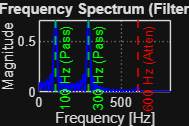


% Filter signal
y_filtered = filter(B2, A2, x_sampled);

% Compute FFT of filtered signal
Y_fft = fft(y_filtered, N_fft);
Y_mag = abs(Y_fft) / length(y_filtered);
Y_onesided = Y_mag(1:N_fft/2+1);
Y_onesided(2:end-1) = 2*Y_onesided(2:end-1);

% Plot
figure('Name', 'Problem 2-5: Filtered Spectrum');
plot(f_onesided, Y_onesided, 'b-', 'LineWidth', 1.5);
hold on;
xline(F1, '--g', sprintf('%d Hz (Pass)', F1), 'LineWidth', 1.5);
xline(F2, '--g', sprintf('%d Hz (Pass)', F2), 'LineWidth', 1.5);
xline(F3, '--r', sprintf('%d Hz (Atten)', F3), 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude');
title('Frequency Spectrum (Filtered)');
xlim([0 Fs2/2]);


% Find amplitudes
[~, idx_100] = min(abs(f_onesided - F1));
[~, idx_300] = min(abs(f_onesided - F2));
[~, idx_600] = min(abs(f_onesided - F3));

A_100_filt = Y_onesided(idx_100);
A_300_filt = Y_onesided(idx_300);
A_600_filt = Y_onesided(idx_600);

fprintf('Filtered signal amplitudes:\n');

Filtered signal amplitudes:


fprintf('Freq\t Original\t Filtered\t Attenuation [dB]\n');

Freq	 Original	 Filtered	 Attenuation [dB]


fprintf('100 Hz\t %.3f\t\t %.3f\t\t %.2f\n', A1, A_100_filt, 20*log10(A_100_filt/A1));

100 Hz	 1.000		 0.700		 -3.09


fprintf('300 Hz\t %.3f\t\t %.3f\t\t %.2f\n', A2, A_300_filt, 20*log10(A_300_filt/A2));

300 Hz	 2.000		 0.710		 -8.99


fprintf('600 Hz\t %.3f\t\t %.3f\t\t %.2f\n\n', A3, A_600_filt, 20*log10(A_600_filt/A3));

600 Hz	 3.000		 0.047		 -36.19




dB_600 = 20*log10(A_600_filt/A3);
fprintf('Attenuation at 600 Hz: %.2f dB\n', dB_600);

Attenuation at 600 Hz: -36.19 dB


fprintf('From frequency response (2-1): %.2f dB\n', Mag_600);

From frequency response (2-1): -27.11 dB


fprintf('Difference: %.2f dB\n', abs(Mag_600 - dB_600));

Difference: 9.07 dB



if abs(Mag_600 - dB_600) < 2
    fprintf('MATCHES - Results consistent\n\n');
else
    fprintf('DISCREPANCY noted\n\n');
end

DISCREPANCY noted




%% ========================================================================
%% PROBLEM 3 (30%) - FIR Filter Design
%% ========================================================================

%%
% *Problem 3: Highpass FIR Filter Design (Windowing Method)*
%
% * Fpass = 1750 Hz, Fstop = 1250 Hz
% * As = 20 dB (later 40 dB)
% * Fs = 5000 Hz

%% Problem 3-1: Window Selection and Order

fprintf('========================================\n');

fprintf('PROBLEM 3: FIR FILTER DESIGN\n');

PROBLEM 3: FIR FILTER DESIGN


fprintf('========================================\n\n');


% Specifications
Fpass = 1750;
Fstop = 1250;
As_dB = 20;
Fs3 = 5000;

fprintf('=== Problem 3-1: Specifications ===\n\n');

=== Problem 3-1: Specifications ===




% Cutoff frequency
Fc = (Fpass + Fstop) / 2;
fprintf('Cutoff frequency: Fc = (%.0f + %.0f)/2 = %.0f Hz\n\n', Fpass, Fstop, Fc);

Cutoff frequency: Fc = (1750 + 1250)/2 = 1500 Hz




% Normalized cutoff
f_til_c = Fc / Fs3;
wc = 2*pi*f_til_c;
fprintf('Normalized cutoff:\n');

Normalized cutoff:


fprintf('  f_c = %.4f cycles/sample\n', f_til_c);

  f_c = 0.3000 cycles/sample


fprintf('  ωc = %.4f rad/sample = %.2fπ\n\n', wc, wc/pi);

  ωc = 1.8850 rad/sample = 0.60π




% Sharpness parameter
Delta_F = Fpass - Fstop;
F_sharpness = Delta_F / Fs3;
fprintf('Sharpness parameter:\n');

Sharpness parameter:


fprintf('  ΔF = %.0f Hz\n', Delta_F);

  ΔF = 500 Hz


fprintf('  Fsharpness = %.4f\n\n', F_sharpness);

  Fsharpness = 0.1000




% Window selection
fprintf('Window selection for As = %.0f dB:\n', As_dB);

Window selection for As = 20 dB:


fprintf('  Hamming: As ≈ 53 dB (recommended)\n\n');

  Hamming: As ≈ 53 dB (recommended)




% Number of taps
Ntaps_3 = 9;
M_3 = Ntaps_3 - 1;
fprintf('Filter order: M = %d, Ntaps = %d\n\n', M_3, Ntaps_3);

Filter order: M = 8, Ntaps = 9




%% Problem 3-2: Impulse Response (Ntaps = 9)

fprintf('=== Problem 3-2: Impulse Response (Ntaps=9) ===\n\n');

=== Problem 3-2: Impulse Response (Ntaps=9) ===




K_3 = (M_3 + 1) / 2;
fprintf('Center index: K = %.1f\n\n', K_3);

Center index: K = 4.5




% Generate ideal highpass
n_ideal_3 = -(M_3/2):(M_3/2);
h_ideal_3 = zeros(size(n_ideal_3));

for i = 1:length(n_ideal_3)
    if n_ideal_3(i) == 0
        h_ideal_3(i) = 1 - wc/pi;
    else
        h_ideal_3(i) = -(wc/pi) * sinc(wc * n_ideal_3(i) / pi);
    end
end

% Apply Hamming window
w_3 = hamming(Ntaps_3)';
h_3 = h_ideal_3 .* w_3;
n_causal_3 = 0:M_3;

fprintf('Impulse response h[n]:\n');

Impulse response h[n]:


fprintf('n\t h[n]\n');

n	 h[n]


for i = 1:length(h_3)
    fprintf('%d\t %.6f\n', n_causal_3(i), h_3(i));
end

0	 -0.006055
1	 0.013392
2	 0.050516
3	 -0.261944
4	 0.400000
5	 -0.261944
6	 0.050516
7	 0.013392
8	 -0.006055


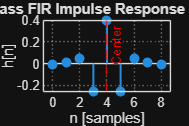

fprintf('\n');

% Plot
figure('Name', 'Problem 3-2: Impulse Response (N=9)');
stem(n_causal_3, h_3, 'filled', 'LineWidth', 1.5);
grid on;
xlabel('n [samples]');
ylabel('h[n]');
title('Highpass FIR Impulse Response (Ntaps=9)');
xline(M_3/2, '--r', 'Center');


%% Problem 3-3: Frequency Response (Ntaps = 9)

fprintf('=== Problem 3-3: Frequency Response (Ntaps=9) ===\n\n');

=== Problem 3-3: Frequency Response (Ntaps=9) ===



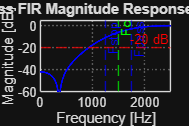


% Compute response
[H_3, F_3] = freqz(h_3, 1, 10000, Fs3);
Mag_3_dB = 20*log10(abs(H_3));

% Plot
figure('Name', 'Problem 3-3: Magnitude (N=9)');
plot(F_3, Mag_3_dB, 'b-', 'LineWidth', 1.5);
hold on;
grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Highpass FIR Magnitude Response (Ntaps=9)');
xlim([0 Fs3/2]);
ylim([-60 5]);

% Mark specifications
xline(Fc, '--g', 'Fc');
xline(Fpass, '--b', 'Fpass');
xline(Fstop, '--b', 'Fstop');
yline(-As_dB, '--r', sprintf('-%.0f dB', As_dB));
hold off;


% Verify
[~, idx_stop] = min(abs(F_3 - Fstop));
As_actual = -max(Mag_3_dB(1:idx_stop));

fprintf('Stopband attenuation:\n');

Stopband attenuation:


fprintf('  Required: >= %.0f dB\n', As_dB);

  Required: >= 20 dB


fprintf('  Actual: %.1f dB\n', As_actual);

  Actual: 10.8 dB


if As_actual >= As_dB
    fprintf('  MEETS SPEC\n\n');
else
    fprintf('  FAILS SPEC (needs higher order)\n\n');
end

  FAILS SPEC (needs higher order)




%% Problem 3-4: Phase Response (Ntaps = 9)

fprintf('=== Problem 3-4: Phase Analysis (Ntaps=9) ===\n\n');

=== Problem 3-4: Phase Analysis (Ntaps=9) ===



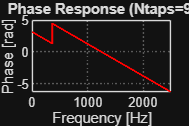


phase_3 = unwrap(angle(H_3));

figure('Name', 'Problem 3-4: Phase (N=9)');
plot(F_3, phase_3, 'r-', 'LineWidth', 1.5);
grid on;
xlabel('Frequency [Hz]');
ylabel('Phase [rad]');
title('Phase Response (Ntaps=9)');
xlim([0 Fs3/2]);


fprintf('Phase characteristic: LINEAR\n');

Phase characteristic: LINEAR


fprintf('Expected? YES - symmetric FIR has linear phase\n');

Expected? YES - symmetric FIR has linear phase


fprintf('Reason: h[n] = h[M-n] → φ(ω) = -ω·M/2\n\n');

Reason: h[n] = h[M-n] → φ(ω) = -ω·M/2




%% Problem 3-5: Redesign with As = 40 dB

fprintf('=== Problem 3-5: Redesign (As = 40 dB) ===\n\n');

=== Problem 3-5: Redesign (As = 40 dB) ===




As_dB_new = 40;
fprintf('New requirement: As = %.0f dB\n\n', As_dB_new);

New requirement: As = 40 dB




% Window selection
fprintf('Window: Hamming (As ≈ 53 dB >= 40 dB)\n\n');

Window: Hamming (As ≈ 53 dB >= 40 dB)




% New order
Ntaps_new = 31;
M_new = Ntaps_new - 1;
fprintf('Filter order: M = %d, Ntaps = %d\n\n', M_new, Ntaps_new);

Filter order: M = 30, Ntaps = 31




% Generate impulse response
n_ideal_new = -(M_new/2):(M_new/2);
h_ideal_new = zeros(size(n_ideal_new));

for i = 1:length(n_ideal_new)
    if n_ideal_new(i) == 0
        h_ideal_new(i) = 1 - wc/pi;
    else
        h_ideal_new(i) = -(wc/pi) * sinc(wc * n_ideal_new(i) / pi);
    end
end

w_new = hamming(Ntaps_new)';
h_new = h_ideal_new .* w_new;
n_causal_new = 0:M_new;

fprintf('First 10 coefficients:\n');

First 10 coefficients:


fprintf('n\t h[n]\n');

n	 h[n]


for i = 1:10
    fprintf('%d\t %.6f\n', n_causal_new(i), h_new(i));
end

0	 -0.000000
1	 -0.001947
2	 0.001724
3	 0.002617
4	 -0.006390
5	 0.000000
6	 0.013382
7	 -0.011505
8	 -0.015718
9	 0.034418


fprintf('...\n\n');

...



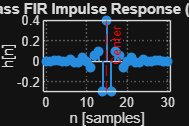


% Plot
figure('Name', 'Problem 3-5: Impulse Response (N=31)');
stem(n_causal_new, h_new, 'filled', 'LineWidth', 1.5);
grid on;
xlabel('n [samples]');
ylabel('h[n]');
title('Highpass FIR Impulse Response (Ntaps=31)');
xline(M_new/2, '--r', 'Center');


%% Problem 3-6: Verification (Ntaps = 31)

fprintf('=== Problem 3-6: Verification (Ntaps=31) ===\n\n');

=== Problem 3-6: Verification (Ntaps=31) ===



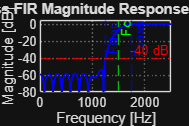


% Compute response
[H_new, F_new] = freqz(h_new, 1, 10000, Fs3);
Mag_new_dB = 20*log10(abs(H_new));

% Plot
figure('Name', 'Problem 3-6: Magnitude (N=31)');
plot(F_new, Mag_new_dB, 'b-', 'LineWidth', 1.5);
hold on;
grid on;
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Highpass FIR Magnitude Response (Ntaps=31)');
xlim([0 Fs3/2]);
ylim([-80 5]);

% Mark specifications
xline(Fc, '--g', 'Fc');
xline(Fpass, '--b', 'Fpass');
xline(Fstop, '--b', 'Fstop');
yline(-As_dB_new, '--r', sprintf('-%.0f dB', As_dB_new));
hold off;


% Verify
[~, idx_stop_new] = min(abs(F_new - Fstop));
As_actual_new = -max(Mag_new_dB(1:idx_stop_new));

fprintf('Stopband attenuation:\n');

Stopband attenuation:


fprintf('  Required: >= %.0f dB\n', As_dB_new);

  Required: >= 40 dB


fprintf('  Actual: %.1f dB\n', As_actual_new);

  Actual: 40.6 dB


if As_actual_new >= As_dB_new
    fprintf('  MEETS SPEC\n\n');
else
    fprintf('  FAILS SPEC\n\n');
end

  MEETS SPEC




fprintf('Filter successfully meets all specifications\n\n');

Filter successfully meets all specifications




%% Summary

fprintf('========================================\n');

fprintf('EXAM COMPLETE\n');

EXAM COMPLETE


fprintf('========================================\n\n');

fprintf('All problems solved and verified\n');

All problems solved and verified
